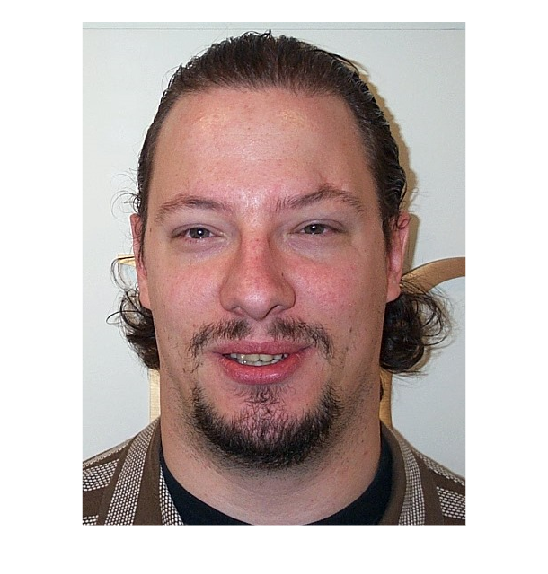

clear
realId = 5; 
% Se till att du är i "/GitHub/TNM034_Projekt" när du läser in 
image = imread("./Faces/db1_" + realId + ".jpg");
imshow(image)

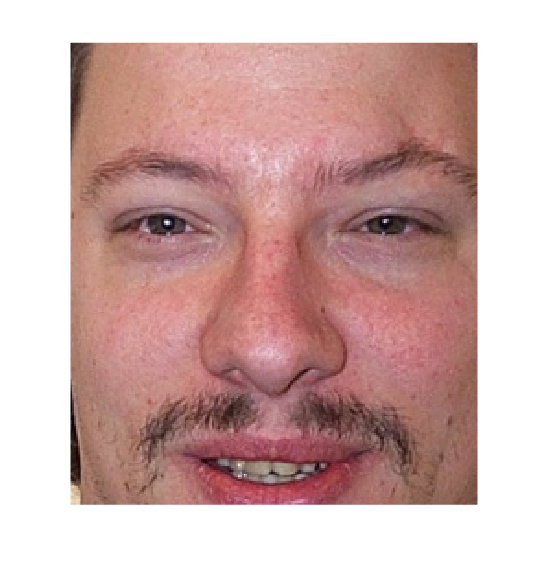


[eye1,eye2] = findEyes(image);

image = faceNormalization(image,eye1,eye2);
imshow(image)

load("traind_model.mat", 'mean_face', 'W', 'U');

image = rgb2gray(image);
x = image(:);
[~, columns] = size(mean_face);
x = repmat(x, 1, columns);
face = double(x) - mean_face;

thisW = U'*face;

% Transpose face to perform calculations column-wise
face = face';

% Calculate distances between W and face vectors
distances = arrayfun(@(i) norm(abs(W(:, i) - thisW(:, i))), 1:size(W, 1));
[distance, id] = min(distances);
threshhold = 0.1;
if(distance < threshhold), out_id = id;
else, out_id = 0;
end
[distance, id] = min(distances);
threshhold= 1.5;
if(distance < threshhold), out_id = id;
else, out_id = 0;
end